**Examples on Linear Models**

Example 1:

                    (LP Pg 27 Q1)

 The manager of a furniture factory finds that it costs Rs. 2200 to manufacture 100 chairs in a day and Rs. 4800 to produce 300 chairs in a day.

(a) Express the cost as a function of the number of chairs produced, assuming that it is linear. Then sketch the graph and interpret.

(b) What is the slope of the graph and what does it represent?

(c) Estimate the cost to produce 400 chairs.

%Equation
syms b m w
C(w) = b + m * w

$$C(w) = b+m\,w$$

eq = [C(100) == 2200 C(300) == 4800]

$$eq = \left(\begin{array}{cc} b+100\,m=2200 & b+300\,m=4800 \end{array}\right)$$

[m, b] = solve (eq, [m, b])

$$m = 13$$

$$b = 900$$

C(w) = subs (C(w))

$$C(w) = 13\,w+900$$


%Graph of the function
fplot (C(w), [0, 500])
grid on
xlabel('Number of chairs')
ylabel('Cost (in Rupees)')

%Slope of the function
slope = m

$$slope = 13$$


%Y-Intercept
y_int = b

$$y\_int = 900$$


%Estimation
C_pred = C(400)

$$C\_pred = 6100$$

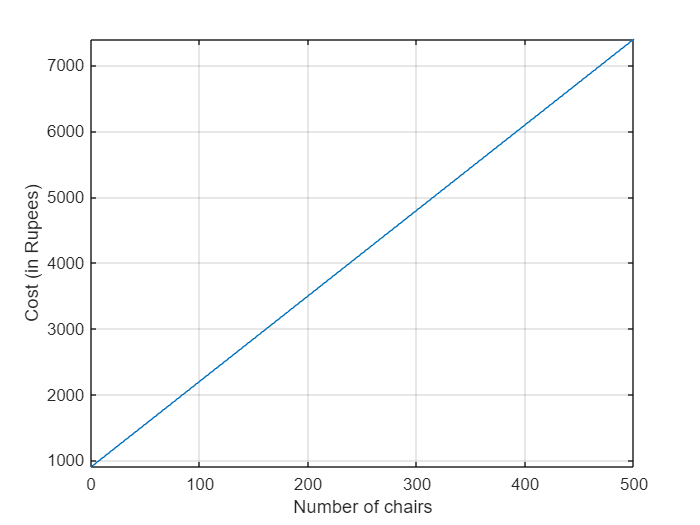


hold on

Example 2:

                    (LP Pg 27 Q2)

Residents of the city Hubballi- Dharwad who are connected to the municipal water supply are billed a fixed amount yearly plus a charge for each cubic foot of water used. A household using 1000 cubic feet was billed Rs. 90, while one using 1600 cubic feet was billed Rs. 105.

(a) Build a mathematical model for the total cost of a resident's water in terms of cubic feet of water used.

(b) How many cubic feet of water used would lead to a bill of Rs. 130?

(c) Sketch the graph.

%Equation
syms b m w
B(w) = b + m * w

$$B(w) = b+m\,w$$

eq = [B(1000) == 90 B(1600) == 105]

$$eq = \left(\begin{array}{cc} b+1000\,m=90 & b+1600\,m=105 \end{array}\right)$$

[m, b] = solve (eq, [m, b])

$$m = \frac{1}{40}$$

$$b = 65$$

B(w) = subs (B(w))

$$B(w) = \frac{w}{40}+65$$

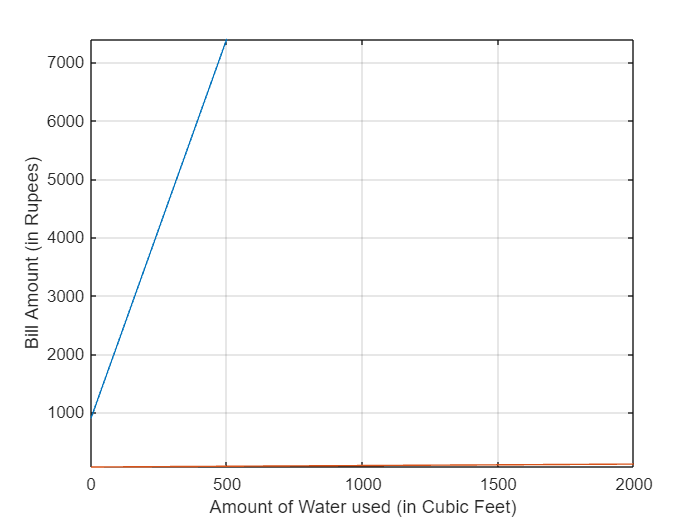


%Graph of the function
fplot (B(w), [0, 2000])
grid on
xlabel('Amount of Water used (in Cubic Feet)')
ylabel('Bill Amount (in Rupees)')

hold on

Example 3:

                    (LP Pg 27 Q3)

Biologists have observed that the chirping rate of cricekts of a certain species appears to be related to temperature. The table shows the chirping rates for various temperatures,

Temperature ($^o$F):    20    22    24    26    28    30    32    34    36

Chirping Rate (Chirps/min):    113    128    143    158    173    188    203    218    233

(a) Make a scatter plot of the data.

(b) Use the linear model to estimate the chirping rate at 40$^o$F

(c) Sketch the graph of model.

%Scatter Plot
syms m b t
temp = [20 22 24 26 28 30 32 34 36]

temp =     20    22    24    26    28    30    32    34    36


Chirp_rate = [113 128 143 158 173 188 203 218 233]

Chirp_rate =    113   128   143   158   173   188   203   218   233


scatter (temp, Chirp_rate, 'ro')

%Equation
c(t) = b + m * t

$$c(t) = b+m\,t$$

eqns = [c(20) == 113 c(36) == 233]

$$eqns = \left(\begin{array}{cc} b+20\,m=113 & b+36\,m=233 \end{array}\right)$$

[m, b] = solve (eqns, [m b])

$$m = \frac{15}{2}$$

$$b = -37$$

c(t) = subs(c(t))

$$c(t) = \frac{15\,t}{2}-37$$


%Estimation
c_pred = c(40)

$$c\_pred = 263$$

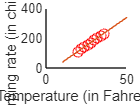


%Graph
hold on
fplot (c(t), [10 50])
xlabel ('Temperature (in Fahrenheit)')
ylabel ('Chirping rate (in chirps/min)')
hold off